# Computer Assignment 1 Report

## Mohammad Saadati                                        810198410

### Part1: Familiarity with MATLAB Software

#### **Sampling Frequency:**

We use sampling (some sample points and their values to show the signal) when we want to convert a continious-time signal to discrete-time signal .Sampling frequency is number of sample points in one period of time.

plot of y=$\mathrm{cos}\left(2\pi \mathrm{ft}\right)$

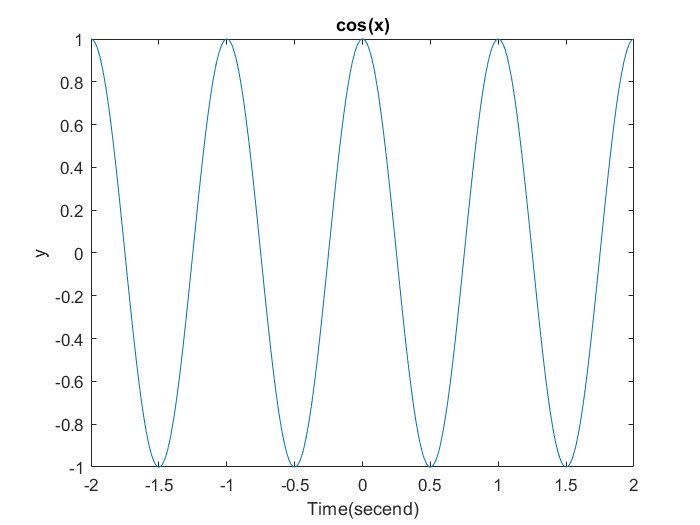

clear;
f = 1;
time_step = 0.001;
t = -2:time_step:2;
y = cos(2*pi*f*t);
plot(t,y)
title cos(x)
ylabel y
xlabel Time(secend)

#### **Fourier Transform:**

**linspace(x1, x2, n): ** generates `n` points. The spacing between the points is `(x2-x1)/(n-1)`.

**numel(A): **returns the number of elements, `n`, in array `A`, equivalent to `prod(size(A))`.

**Frequency vector**

fs = 1/time_step;
f = linspace(-fs/2, fs/2, numel(y));

**Plot of magnitude and phase of Fourier transform**

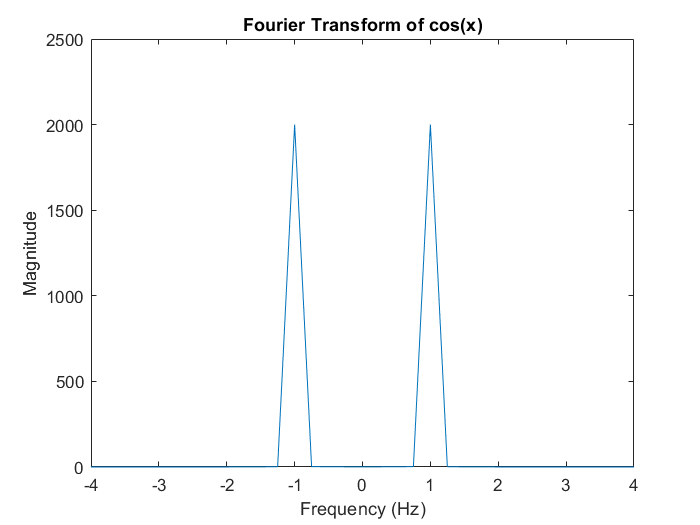

ft = fftshift(fft(y));
phase = angle(ft);
plot(f, abs(ft))
title("Fourier Transform of cos(x)");
xlim([-4,4]);
ylabel("Magnitude");
xlabel("Frequency (Hz)");

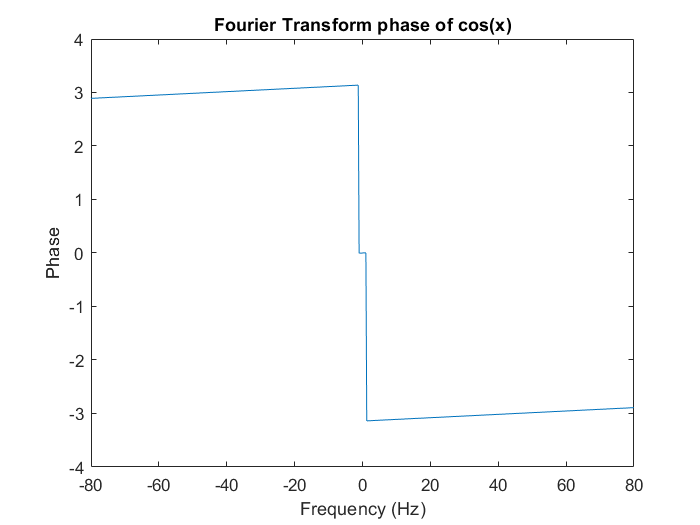

plot(f, phase);
title("Fourier Transform phase of cos(x)");
xlim([-80, 80]);
ylabel("Phase");
xlabel("Frequency (Hz)");

Fourier Transform of cos(x):

As we seen in the diagram, the Fourier Transfor of cos(x) consists of two impulse in points  and  .

### **Part 2: Sleep Status Processing**

In this part we want to process an EEG signal.

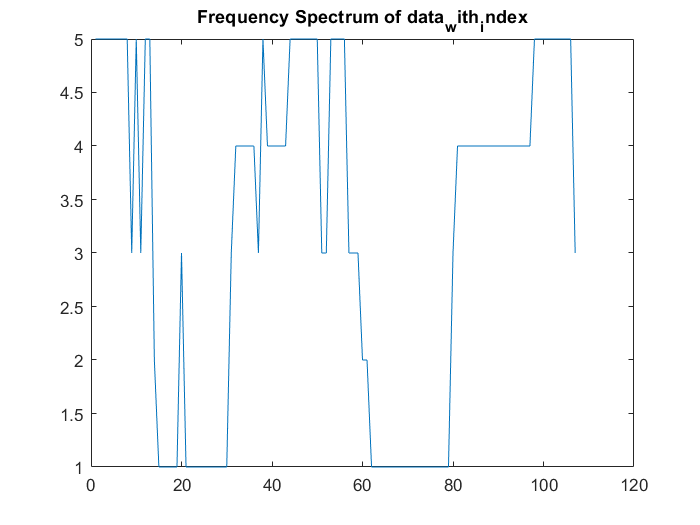

clear;
data = load("Data/EEG_Sleep_Cycle/data.mat");
data_with_index = zeros(1,107);
for i = 1: 107
    if data.data{1,i} == "qt"
        data_with_index(i) = 1;
    elseif data.data{1,i} == "qh"
        data_with_index(i) = 2;
    elseif data.data{1,i} == "tr"
        data_with_index(i) = 3;
    elseif data.data{1,i} == "al"
        data_with_index(i) = 4;
    elseif data.data{1,i} == "ah"
        data_with_index(i) = 5;
    elseif data.data{1,i} == "aw"
        data_with_index(i) = 6;
    end
end
ts = 1;
t = 1:ts:107;
plot(t, data_with_index(t));
title("Frequency Spectrum of data_with_index");

#### **Fourier Transform of data_index:**

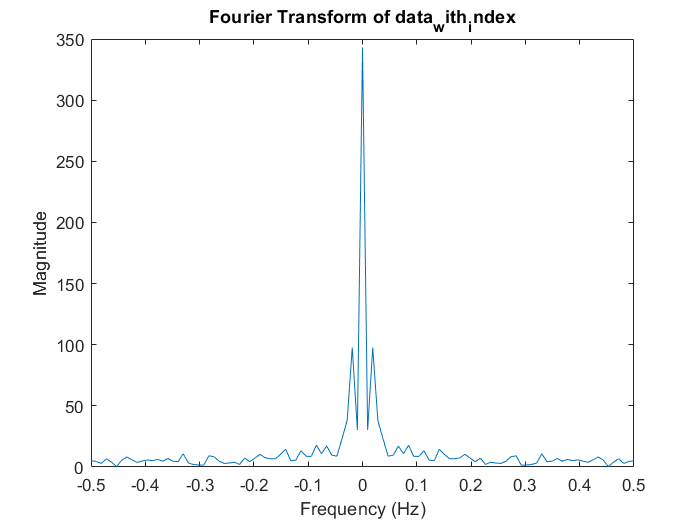

fs = 1/ts; 
fv1 = linspace(-fs/2, fs/2, numel(data_with_index));
ft1 = fftshift(fft(data_with_index));
plot(fv1, abs(ft1))
title("Fourier Transform of data_with_index");
xlabel("Frequency (Hz)");
ylabel("Magnitude");

Now we change the order of indexes:

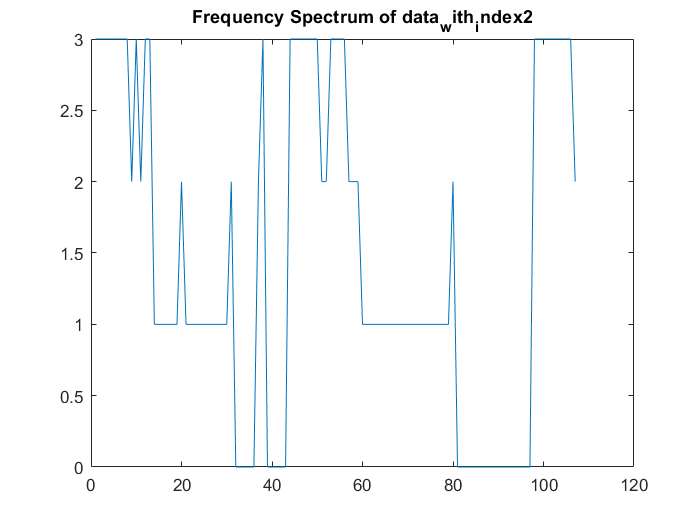

data_with_index2 = zeros(1,107);
for i = 1: 107
    if data.data{1,i} == "qt"
        data_with_index2(i) = 1;
    elseif data.data{1,i} == "qh"
        data_with_index2(i) = 1;
    elseif data.data{1,i} == "tr"
        data_with_index2(i) = 2;
    elseif data.data{1,i} == "al"
        data_with_index(i) = 2;
    elseif data.data{1,i} == "ah"
        data_with_index2(i) = 3;
    elseif data.data{1,i} == "aw"
        data_with_index2(i) = 3;
    end
end
ts = 1;
t = 1:ts:107;
plot(t, data_with_index2(t));
title("Frequency Spectrum of data_with_index2");

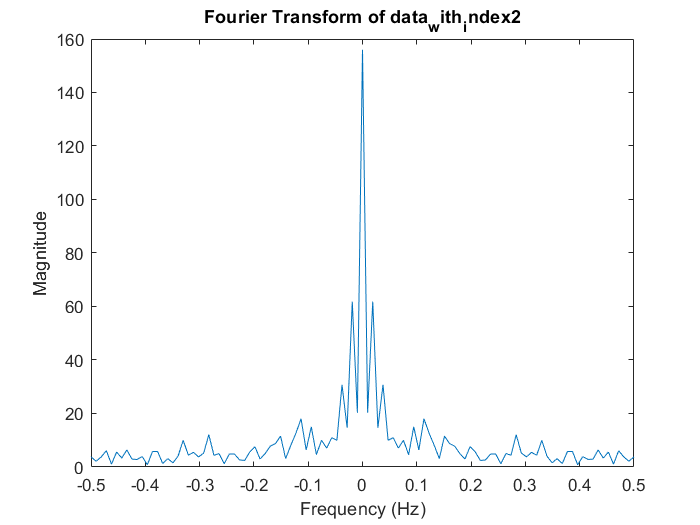

fv2 = linspace(-fs/2, fs/2, numel(data_with_index2));
ft2 = fftshift(fft(data_with_index2));
plot(fv2, abs(ft2))
title("Fourier Transform of data_with_index2");
xlabel("Frequency (Hz)");
ylabel("Magnitude");

### **Part 3: Sound and Music Processing**

clear;
notes = dir(strcat("Data\Piano\", "*.mp3"));
i = 1;
for note = notes'
    [data{i}, fs{i}] = audioread(strcat("Data\Piano\", note.name));
    i = i + 1;
end

**Fourier Transform of two different notes:**

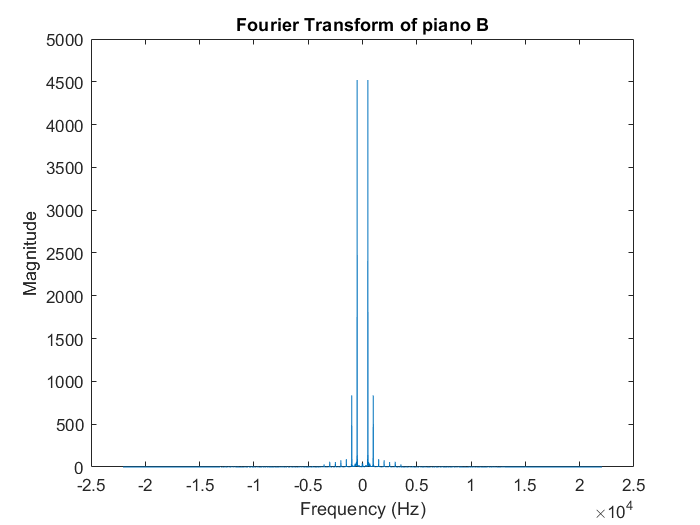

f1 = linspace(-fs{3}/2, fs{3}/2, numel(data{3}));
f2 = linspace(-fs{10}/2, fs{10}/2, numel(data{10}));
ft1 = fftshift(fft(data{3}));
ft2 = fftshift(fft(data{10}));
plot(f1, abs(ft1));
title("Fourier Transform of piano B");
ylabel("Magnitude");
xlabel("Frequency (Hz)");

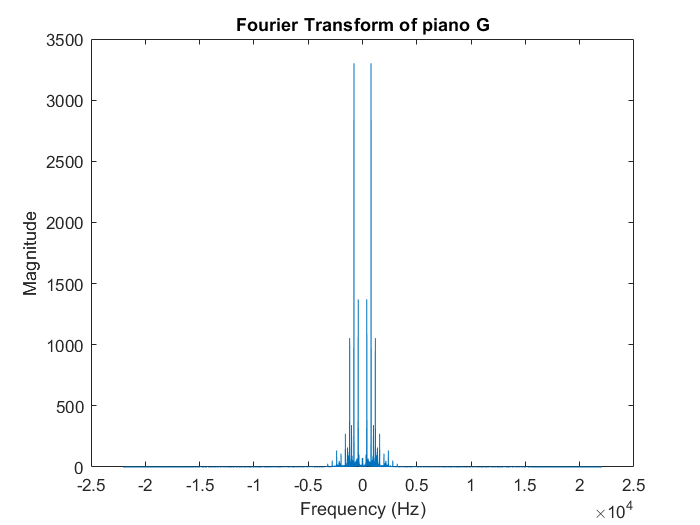

plot(f2, abs(ft2));
title("Fourier Transform of piano G");
ylabel("Magnitude");
xlabel("Frequency (Hz)");

**Now we listen to the sound of these two notes:**

sound(data{3}, fs{3});
sound(data{10}, fs{10});

piano_B consists of signals with lower frequencies so we expect it to have bassier sound than piano_G and also listening to these two notes confirms this fact which are also seen in plots of fourier transform of piano_B and piano_G.